# **Procesamiento de Imágenes Digitales**

**Calibración de Cámaras y Principios de Visión 3D**

#### **Parametros de Calibración**

Cargue los archivos que contienen los parámetros de calibración, y de acuerdo con la información, digite la matriz de la cámara, y la matriz de rotación y el vector de traslación para la imagen 1.

load('Intrinsec.mat');
load('Extrinsec.mat');

#### Coordenadas tridimensionales

A partir de las coordenadas de las esquinas del *checkboard* respecto al sistema del mundo, para la imagen 2, y sus respectivos parámetros extrínsecos, calcule las coordenadas 3D respecto al sistema coordenado de la cámara y grafíquelos (usando asteriscos azules) en el espacio como se muestra a modo de ejemplo para la imagen 1. 

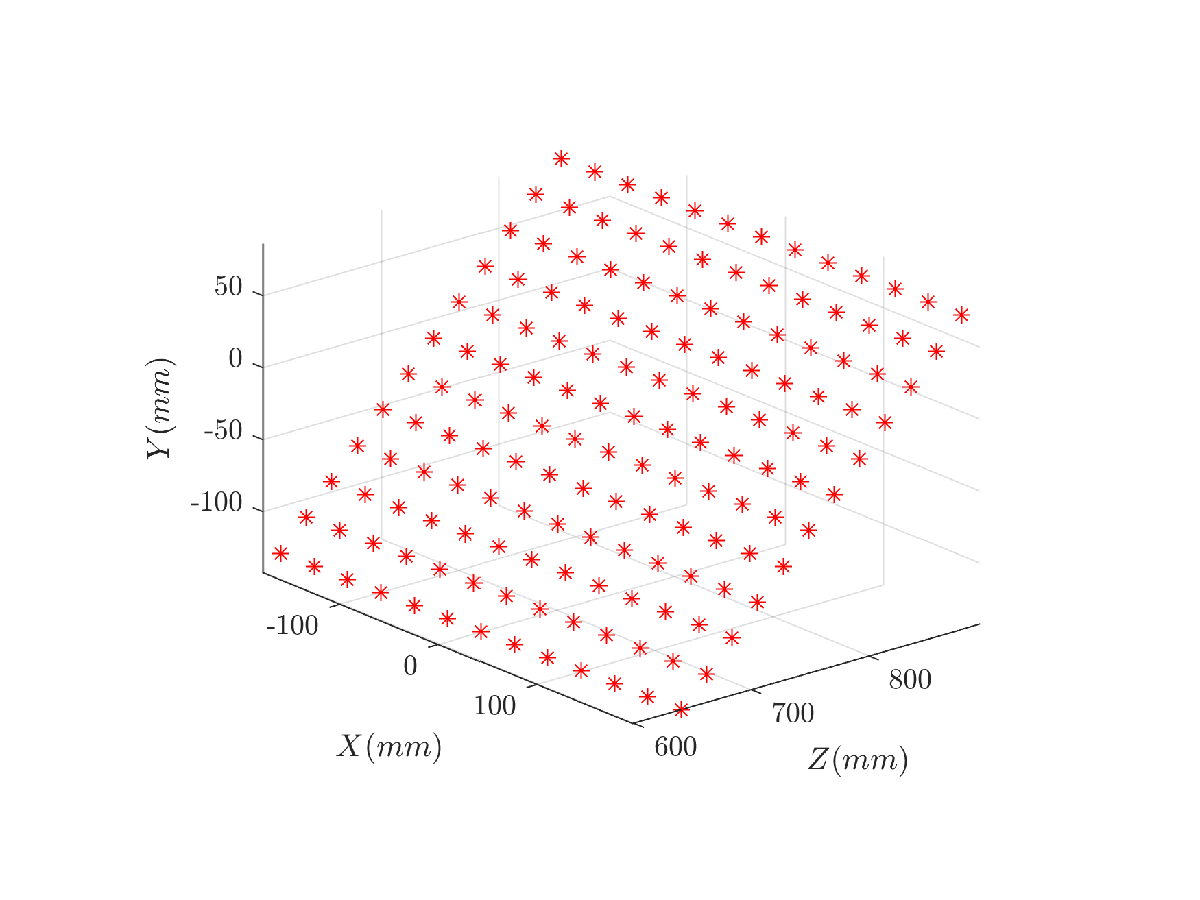

Utilice los comandos `axis equal, view(50,20), axis vis3d, grid on.`

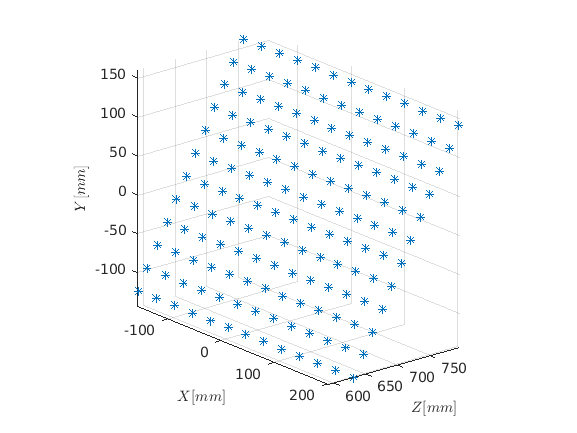

I_2 = Rc_2*X_2 + Tc_2;
plot3(I_2(1,:,:), I_2(3,:,:), -I_2(2,:,:), '*');
xlabel('$X [mm]$','interpreter','latex');
ylabel('$Z [mm]$','interpreter','latex');
zlabel('$Y [mm]$','interpreter','latex');
axis equal
view(50,20)
axis vis3d
grid on

#### Coordenadas tridimensionales respecto al sistema coordenado de la cámara

Utilizando los parámetros intrínsecos y extrínsecos (para las 12 imagenes de calibración), puede graficar en 3D las coordenadas de los puntos de las esquinas del *checkboard* en un `mesh` respecto al sistema coordenado de la cámara, para simular la posición espacial en la que estaba el patrón de calibración cuando fue visto por la cámara para tomar la imagen. A modo de ejemplo, se muestra la siguiente figura con los planos 1 y 2 vistos en 3D respecto al sistema coordenado de la cámara (utilice los colores `'rgbkmyc'`). 

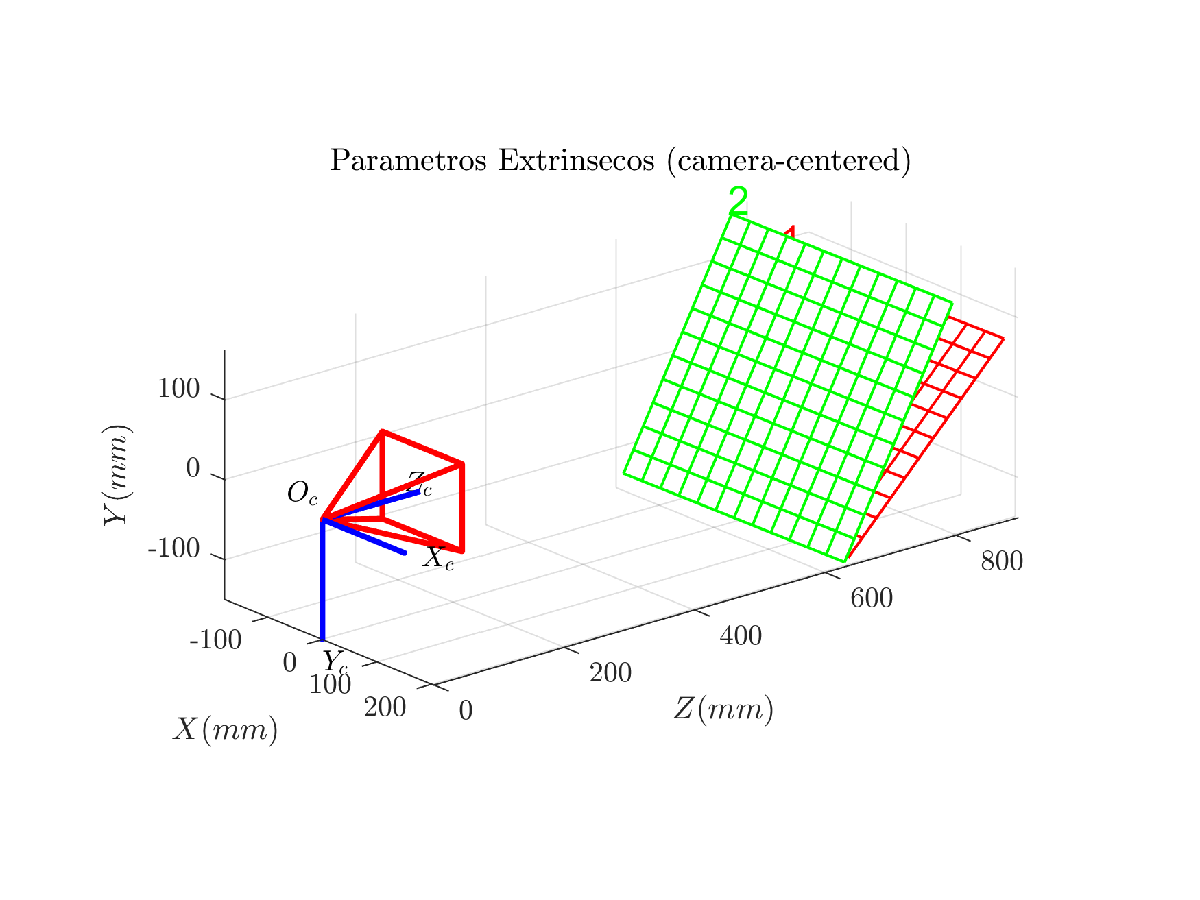

Puede simular la cámara con las siguientes lineas de codigo:

`IP = 5*dX*[1 0 0;0 1 0;0 0 1]*[1/KK(1,1) 0 0;0 1/KK(2,2) 0;0 0 1]*[1 0 -KK(1,3);0 1 -KK(2,3);0 0 1]*[0 nx-1 nx-1 0 0 ; 0 0 ny-1 ny-1 0;1 1 1 1 1];`

`BASE = 5*dX*([0 1 0 0 0 0;0 0 0 1 0 0;0 0 0 0 0 1]);`

`IP = reshape([IP;BASE(:,1)*ones(1,5);IP],3,15);`

`figure;`

`plot3(BASE(1,:),BASE(3,:),-BASE(2,:),'b-','linewidth',2);`

`hold on;`

`plot3(IP(1,:),IP(3,:),-IP(2,:),'r-','linewidth',2);`

`text(6*dX,0,0,'$X_{c}$','Interpreter','latex');`

`text(-dX,5*dX,0,'$Z_{c}$','Interpreter','latex');`

`text(0,0,-6*dX,'$Y_{c}$','Interpreter','latex');`

`text(-dX,-dX,dX,'$O_{c}$','Interpreter','latex');`

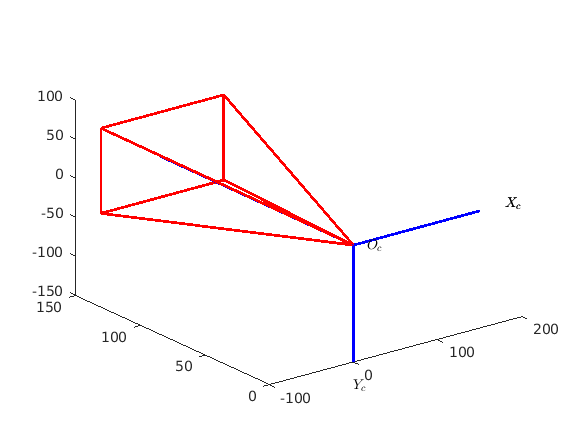

IP = 5*dX*[1 0 0;0 1 0;0 0 1]*[1/KK(1,1) 0 0;0 1/KK(2,2) 0;0 0 1]*[1 0 -KK(1,3);0 1 -KK(2,3);0 0 1]*[0 nx-1 nx-1 0 0 ; 0 0 ny-1 ny-1 0;1 1 1 1 1];
BASE = 5*dX*([0 1 0 0 0 0;0 0 0 1 0 0;0 0 0 0 0 1]);
IP = reshape([IP;BASE(:,1)*ones(1,5);IP],3,15);
figure;
plot3(BASE(1,:),BASE(3,:),-BASE(2,:),'b-','linewidth',2);
hold on;
plot3(IP(1,:),IP(3,:),-IP(2,:),'r-','linewidth',2);
text(6*dX,0,0,'$X_{c}$','Interpreter','latex');
text(6*dX,0,0,'$X_{c}$','Interpreter','latex');
text(0,0,-6*dX,'$Y_{c}$','Interpreter','latex');
text(-dX,-dX,dX,'$O_{c}$','Interpreter','latex');

I_1 = Rc_1*X_1 + Tc_1;
x,y,z = meshgrid(I_1(1), I_1(2), I_1(3))

x =   527.7351  520.4654  513.2467  506.0914  499.0145  492.0319  485.1593  478.4108  471.7989  465.3341  459.0248  452.8776  499.6254  492.7350  485.8992  479.1319  472.4487  465.8655  459.3970  453.0564  446.8547  440.8012  434.9030  429.1654  470.8515  464.3586  457.9277  451.5731  445.3103  439.1539  433.1174  427.2122  421.4481  415.8326  410.3713  405.0682  441.4568  435.3819  429.3790  423.4624  417.6462  411.9434  406.3657  400.9226  395.6220  390.4695  385.4692  380.6236  411.5018  405.8656
  104.4500  132.7275  160.2071  186.8613  212.6663  237.6041  261.6639  284.8420  307.1417  328.5723  349.1486  368.8900   99.7961  128.4015  156.2000  183.1595  209.2532  234.4615  258.7725  282.1824  304.6945  326.3189  347.0710  366.9713   95.1795  124.0970  152.1978  179.4462  205.8129  231.2768  255.8254  279.4547  302.1682  323.9766  344.8962  364.9483   90.6262  119.8350  148.2174  175.7347  202.3555  228.0576  252.8278  276.6621  299.5644  321.5458  342.6234  362.8193   86.1612  115

y =   433.5519  438.2410  443.1510  448.2937  453.6811  459.3256  465.2397  471.4358  477.9267  484.7251  491.8442  499.2985  412.6532  416.8341  421.2168  425.8124  430.6326  435.6891  440.9939  446.5592  452.3969  458.5193  464.9383  471.6666  391.4215  395.0692  398.8972  402.9161  407.1366  411.5700  416.2276  421.1209  426.2614  431.6606  437.3299  443.2806  369.8828  372.9738  376.2215  379.6354  383.2256  387.0023  390.9761  395.1577  399.5580  404.1876  409.0574  414.1779  348.0668  350.5794
  195.4542  208.3911  222.0360  236.4375  251.6475  267.7209  284.7156  302.6925  321.7154  341.8511  363.1691  385.7427  193.9755  206.9585  220.6611  235.1339  250.4308  266.6089  283.7287  301.8541  321.0517  341.3912  362.9449  385.7883  192.5038  205.5267  219.2800  233.8161  249.1907  265.4634  282.6972  300.9585  320.3172  340.8459  362.6202  385.7182  191.0424  204.0989  217.8955  232.4864  247.9291  264.2853  281.6204  300.0037  319.5078  340.2085  362.1847  385.5175  189.5949  202

z = 178.9849

mesh(x,z,y)

Error using mesh (line 71)
Data dimensions must agree.

%plot3(I_1(1,:,:), I_1(3,:,:), -I_1(2,:,:));
I_2 = Rc_2*X_2 + Tc_2;
%plot3(I_2(1,:,:), I_2(3,:,:), -I_2(2,:,:));
xlabel('$X [mm]$','interpreter','latex');
ylabel('$Z [mm]$','interpreter','latex');
zlabel('$Y [mm]$','interpreter','latex');
title('parametros extrinsecos (camera-centerd)','interpreter','latex')
axis equal
view(50,20)
axis vis3d
grid on